## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Johannes Langelaar](https://ch.mathworks.com/matlabcentral/profile/authors/8723697)

The mnist data on handwritten digits is already preprocessed and ready to use.

Mathworks: https://ch.mathworks.com/matlabcentral/fileexchange/90461-neural-network-training-with-adam-optimizer-from-scratch/?s_tid=LandingPageTabfx

Originaly there are **60'000** digits to train the model and **10'000** for testing. To increase the difficulty and have a better comparability between methods, only **20'000** digits were used for training and **5000** for testing. 

**Explanation for the usage of genetic algorithms in neural networks**

https://towardsdatascience.com/gas-and-nns-6a41f1e8146d

### NN-Architecture

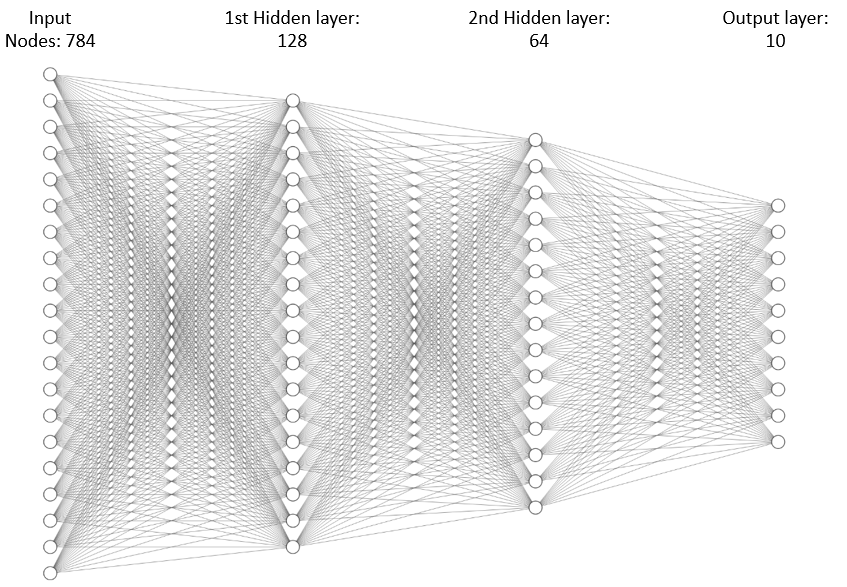

#### Input digits (28X28)

#### Project goal:

The first goal of the project is to evaluate different optimization methods to imporve the backpropagation of the model. The methods used are:

- Gradient descent 

- Mini-batch gradient descent 

- Stochastic gradient descent -X

- Adagrad. -X

- Adadelta. -X     

- RMSprop.

- Adam. -X

The second goal is to implement a genetic algorithm which finds the best initial weights for the first hidden layer to increase the accuracy. 

As a workflow template we use the publication of Ecer et al. https://www.mdpi.com/1099-4300/22/11/1239

The following steps were implemented:

- Train 10 individual models over 3 epochs with random weights. 

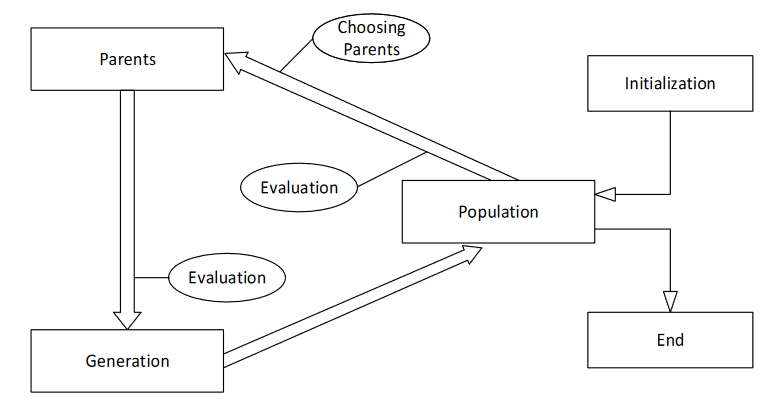

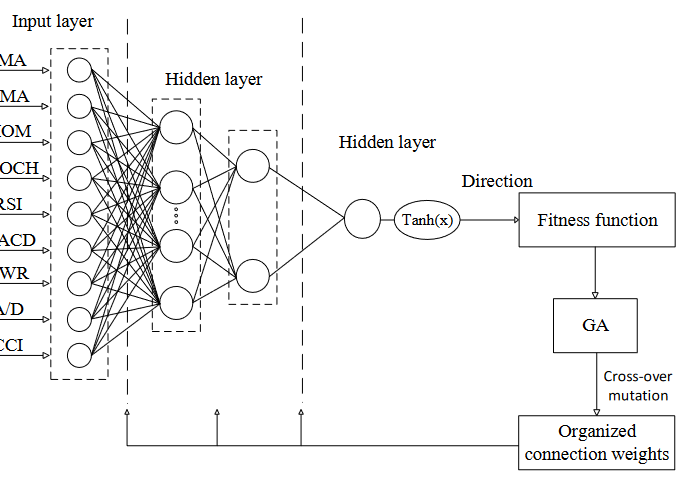

#### Data preprocessing

%cd 'C:\Users\kevin yar\OneDrive - ZHAW\KEVIN STUFF\ZHAW\_PYTHON_R\_GITHUB\becs4\neural_network_mninst'
%cd neural_network_mninst\

%% training data
disp('Loading data...')

Loading data...



% load train data
train_data = load('mnist_train.csv');

%reduce data volume to increase difficulty
train_data = train_data(1:10000,:);

%start progress bar
f = waitbar(0, 'Starting');

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    waitbar(i/length(train_data), f, sprintf('Training Data: %d %%', floor(i/length(train_data)*100)));
    %one hot encoding
    y(labels(i)+1,i) = 1;
end
close(f)
% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

%% test data
    
% load test data
test_data = load('mnist_test.csv');
%reduce test data
test_data = test_data(1:5000, :);

%progress bar
f = waitbar(0, 'Starting');

test_labels = test_data(:,1);
test_y = zeros(10 ,length(test_data));
for i = 1:length(test_data)
    waitbar(i/length(test_data), f, sprintf('Test Data: %d %%', floor(i/length(test_data)*100)));
    test_y(test_labels(i)+1,i) = 1;
end
close(f)
% preproessing
test_images = test_data(:,2:785);
% normalize data
test_images = test_images/255;
% transposing
test_images = test_images';


## **Optimizer comparison**

To evaluate the performance of the added optimizers the models are trained over 5 epochs. 

**Specify hyperparameters for **


%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

%set learning rate
lr = 0.001;

epochs = 3; % Number of training epochs
batch_size = 100; % Mini-batch size

visModels = VisualizeOptMethods(epochs, ...
                                batch_size, ...
                                size_hl1, ...
                                size_hl2, ...
                                lr, ...
                                train_data, ...
                                images, ...
                                y, ...
                                test_data, ...
                                test_images, ...
                                test_labels)

epoch
     1



obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2681
        rmse: 0.2681
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2600
        rmse: [0.2681 0.2600]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.2587
        rmse: [0.2681 0.2600 0.2587]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.2403
        rmse: [0.2681 0.2600 0.2587 0.2403]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.2554
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.2631
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2672
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.2871
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.2565
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.2540
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.2886
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.2672
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.2787
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.2735
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.2606
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.2352
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.2587
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.2741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.2590
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.2680
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2542
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.2589
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.2577
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2429
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.2555
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2799
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.2414
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.2857
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.2654
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.2454
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2820
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2854
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.2659
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.2728
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 0.2728]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2636
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.2582
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.2884
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.2622
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.2332
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.2729
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.2564
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.2550
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.2390
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2623
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.2717
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.2594
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.2566
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.2609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.2647
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.2800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2751
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.2704
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.2442
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.2467
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.2628
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.2639
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.2725
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.2688
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.2544
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.2428
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.2616
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.2517
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.2736
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.2638
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.2579
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.2680
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2722
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.2473
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.2540
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.2645
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.2582
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.2421
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2574
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.2815
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2737
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.2526
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.2574
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.2456
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.2493
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2405
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.2616
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.2570
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.2888
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.2758
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.2387
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.2591
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.2838
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.2738
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.2681
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.2542
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.2692
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.2460
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2479
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.2801
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.2610
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2645
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.2356
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.2668
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.2749
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.2471
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2466
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2239
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.2440
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.2226
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.2485
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.2342
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2504
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.2606
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.2454
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.2492
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.2468
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.2567
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.2449
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.2364
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.2337
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.2400
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.2484
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.2273
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.2458
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.2291
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2327
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.2278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.2430
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.2418
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2329
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.2472
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.2301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.2468
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.2450
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2681
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2349
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.2513
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.2527
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2436
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.2562
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.2563
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.2362
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.2546
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.2355
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.2264
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.2259
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.2321
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2335
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.2349
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.2495
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.2367
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.2497
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.2229
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.2592
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2397
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.2440
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.2414
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.2530
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.2456
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.2522
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.2362
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.2611
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.2379
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.2379
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.2460
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.2442
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.2418
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.2355
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.2346
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.2435
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2365
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.2542
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.2204
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.2393
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.2432
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.2426
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2410
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.2498
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2454
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.2553
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.2389
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.2375
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.2417
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2512
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.2402
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.2468
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.2444
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.2481
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.2468
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.2261
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.2560
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.2262
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.2381
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.2310
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.2379
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.2484
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2375
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.2224
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.2366
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2554
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.2246
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.2488
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.2609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.2398
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2357
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2246
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.2260
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.2301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.2385
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.2235
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2197
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.2417
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.2279
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.2149
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.2433
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.2284
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.2162
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.2156
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1980
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.2452
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.2217
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.2276
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.2369
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.2293
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2181
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.2191
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.2134
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2082
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.2219
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2184
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.2302
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.2393
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.2476
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.2223
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2145
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2267
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.2358
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.2202
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2315
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.2437
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.2307
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.2210
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.2449
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.2348
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.2302
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.2365
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.2381
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2015
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.2241
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.2224
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.2260
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.2400
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.2384
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.2229
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2477
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.2232
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.2079
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.2102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.2457
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.2409
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.2332
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.2273
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.2176
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.2291
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.2332
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.2176
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.2241
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.2050
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.2373
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.2245
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2268
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.2331
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.2211
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.2281
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.2349
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.2252
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2113
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.2309
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2413
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.2238
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.2365
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.2219
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.2415
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2455
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.2462
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.2440
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.2435
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.2034
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.2259
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.2401
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.2154
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.2255
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.2102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.2245
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.2292
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.2411
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2154
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.2039
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.2181
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2300
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.2210
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.2252
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.2402
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.2336
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2051
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1917
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.2105
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1814
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.2278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1984
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2039
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1948
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1877
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.2179
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.2273
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.2071
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1908
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.2323
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.2106
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.2188
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.2201
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1873
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.2042
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.2339
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2013
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.2283
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.2396
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2125
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1826
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2009
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.2079
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.2272
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.2064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.2109
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2247
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2131
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.2208
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1992
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2258
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.2212
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.2077
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.2059
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.2019
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1912
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.2297
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.2099
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2133
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.2262
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.2172
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.2256
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1959
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1989
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1906
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2222
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.2131
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.2041
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1966
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.2108
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.2137
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.2397
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.2121
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.2252
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.2012
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.2247
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.2273
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.2052
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.2316
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1971
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2271
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.2064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.2158
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.2079
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1867
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2141
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.2044
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2143
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.2140
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.2016
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2182
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.2141
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1911
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.2120
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.2289
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1854
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.2011
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.2321
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.2345
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.2057
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1878
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2319
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.2123
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.2293
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2065
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.2310
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.2145
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.2234
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1828
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1672
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2013
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.2080
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1945
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.2212
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2133
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.2107
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.2146
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.2259
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1797
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1803
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.2066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.2049
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1885
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1913
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1989
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.2181
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.2277
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.2238
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1939
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.2022
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2281
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.2021
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2212
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1332
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1626
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.2121
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1636
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2009
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.2035
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.2131
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2219
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1902
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.2098
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1862
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.2032
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1673
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.2262
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1974
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2067
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.2147
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1953
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1837
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.2030
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1760
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1984
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2105
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1853
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.2116
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1768
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.2159
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.2063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.2036
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1815
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1726
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.2146
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.2158
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1910
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1695
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.2183
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1739
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1885
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2172
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1805
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1943
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.2064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.2175
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.2243
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2103
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1792
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2108
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.2046
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1903
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1797
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1608
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2082
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1839
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1915
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.2233
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1817
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.2158
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.2066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.2081
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.2305
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.2167
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1964
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.2154
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.2061
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2020
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1851
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.2065
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2032
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.2026
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1854
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.2100
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.2038
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2218
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2145
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.2090
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1957
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1711
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1520
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.2013
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1902
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1951
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.2063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1746
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1871
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1935
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.2074
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1524
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1865
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1745
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1704
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1531
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.2025
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1412
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1499
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.2017
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1770
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.2139
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1567
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.2076
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1650
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1744
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1738
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1988
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.2030
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1985
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.2063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.2071
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1683
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.2080
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1770
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1681
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.2025
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1810
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1817
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.2081
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.2084
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1448
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.2030
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.2087
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1569
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1995
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1928
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1674
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1579
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1977
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1944
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1787
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1884
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.2077
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1655
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1549
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1721
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1826
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.2101
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1823
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1620
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1777
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1291
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.2010
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1962
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.2133
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1963
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1566
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1982
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.2038
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.2045
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1962
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1782
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.2167
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1931
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1825
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1946
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.2111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1437
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.2179
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1944
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1901
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.2187
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1656
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.2045
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1761
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1675
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.2034
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.2045
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1701
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1502
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.2144
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1661
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1473
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1852
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1386
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1802
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1716
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1626
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1848
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1721
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1816
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1521
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1523
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1985
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1545
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1523
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.2131
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1583
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1486
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.1709
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1865
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1810
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1913
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.2145
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.2006
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1271
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1518
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1759
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1719
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1715
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1944
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1487
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1317
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1961
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1236
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1676
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1677
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1802
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1678
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1979
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1787
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1658
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1440
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1867
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1452
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1554
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1546
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1423
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1700
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1935
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1962
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1679
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1659
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1586
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1323
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1919
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1684
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1529
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1711
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1421
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1952
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1735
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1652
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1410
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1863
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1787
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1955
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1495
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1727
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1608
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1637
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1982
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1321
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1362
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1745
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1642
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1908
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1566
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1430
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1844
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1723
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1620
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1384
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1761
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1842
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1755
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1540
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1809
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1695
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1610
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1569
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1477
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1162
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1754
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1564
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1868
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1624
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1344
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1804
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1660
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1413
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1015
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1472
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1652
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1100
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1367
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1627
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1397
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1677
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1525
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1493
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1040
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.1603
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1649
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1775
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1706
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1359
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1165
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1688
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1222
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1285
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1492
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1591
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1683
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1697
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1999
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1626
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1570
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1776
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1608
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1225
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1890
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1324
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1563
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1722
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1593
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1426
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1343
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1455
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1660
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1167
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1871
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1764
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1489
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1463
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1520
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1649
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1834
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1603
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1707
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1778
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1491
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1679
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1680
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1591
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.2034
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1506
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1722
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1318
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1188
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1693
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1507
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1582
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1662
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1797
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1234
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1978
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1660
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1607
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1611
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1484
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1669
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1382
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1548
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1585
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1819
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1297
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1756
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1395
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1274
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1555
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1636
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1261
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1593
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1079
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1345
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1371
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1650
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1292
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1790
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1565
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1538
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1600
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1765
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1147
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0949
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1386
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1552
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1431
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1445
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1036
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1179
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1500
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1989
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1494
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1429
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.1247
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1766
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1724
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1411
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1574
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1052
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1488
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1589
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1534
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1405
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1554
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1543
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1378
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1736
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1106
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1462
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1427
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1352
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1667
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1223
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1276
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1570
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1250
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1324
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1214
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1445
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1275
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1636
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1134
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1248
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1277
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1711
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1507
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1622
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1209
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1226
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1500
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1045
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1386
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.2008
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1532
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1233
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1519
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1369
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1341
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1737
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1595
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1358
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1499
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1412
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1626
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1377
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1718
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1647
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1122
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1561
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1324
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0827
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1347
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1425
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1374
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1656
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1186
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1323
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1512
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1591
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1902
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0918
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1280
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1432
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1176
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1068
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1598
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1860
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1422
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1724
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1268
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0781
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1486
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1319
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.0841
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1379
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1471
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0801
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1438
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1442
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1307
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1462
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1190
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.0961
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1480
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1448
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1366
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1767
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1379
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1259
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.1347
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1233
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1147
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1060
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1603
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1571
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1601
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1191
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1618
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1244
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1212
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1746
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1647
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1688
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0625
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1399
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1378
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1395
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0868
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1596
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0912
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1176
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.0640
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1525
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1345
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1402
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0826
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1566
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1299
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1316
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1438
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1358
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1177
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1605
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1073
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1416
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1338
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1238
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1673
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1123
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1191
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0840
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1234
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1154
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1337
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1497
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1533
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1293
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1359
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1566
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1785
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1250
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1646
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0689
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1556
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1435
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1408
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1404
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1462
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1152
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1223
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0915
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1155
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1179
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1430
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1671
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.0836
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0750
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1485
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1204
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1645
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1524
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1229
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0609
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1694
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1510
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1581
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1397
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1305
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1362
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1107
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1415
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0847
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0938
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1521
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1423
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0652
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1186
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1322
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1628
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1235
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0678
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1344
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1409
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1335
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1319
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1380
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.1466
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1243
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1679
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1134
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1139
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1054
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1696
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1167
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0988
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1449
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1461
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1371
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1559
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1163
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1074
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1349
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0922
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0637
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1478
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1321
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1503
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0901
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0850
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1245
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1098
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1444
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1522
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1093
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0849
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1468
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1598
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0976
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1223
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1370
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1528
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1568
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1150
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1431
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1348
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1659
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1545
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1305
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1323
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1330
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1491
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1168
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0649
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1237
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1118
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0993
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1206
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1421
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1126
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1512
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1843
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1594
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1008
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1426
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1462
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1476
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1326
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1504
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1228
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1210
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1344
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1365
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1080
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1594
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.0840
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1320
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1497
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1351
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1193
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1246
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1302
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1027
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1178
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0985
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1007
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.1240
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0964
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1299
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1226
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1424
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.1464
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0714
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1279
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1308
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1430
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1490
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1387
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1480
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1368
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1270
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1466
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0720
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0648
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1228
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0909
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1256
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1558
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1518
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1181
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0841
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1210
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1243
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1082
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1541
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1294
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0941
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1224
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1400
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1122
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1206
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1253
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1214
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1329
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1297
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.1216
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1365
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1301
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1070
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0675
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1535
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0876
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0799
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1156
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1325
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1162
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1374
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1040
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1083
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1373
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1188
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1143
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1383
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1533
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1427
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1237
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1195
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1183
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1483
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1312
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0991
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1354
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1598
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1098
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1028
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1207
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1475
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1156
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1194
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0749
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1241
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1607
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0464
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1382
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1182
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1354
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1077
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1189
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1246
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1189
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1318
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1103
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.1144
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1227
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0500
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0891
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1109
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0413
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1038
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.1114
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1061
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0928
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1113
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.0675
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0477
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1192
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1128
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.0966
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1180
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1141
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1136
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1319
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0428
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1124
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0945
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1296
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0592
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1274
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0366
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1069
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1108
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1169
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1127
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1383
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1159
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1439
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1114
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1537
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1198
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1138
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1000
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0921
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1089
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1080
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0859
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1347
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0423
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1300
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1062
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1094
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.0881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.1485
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1153
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1065
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1109
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1278
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.1062
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.0829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0831
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0814
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.0892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1150
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1096
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.1063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1098
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1064
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.1019
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1261
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1039
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1241
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0999
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0992
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1098
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0964
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1108
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1055
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0500
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.1317
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1015
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1645
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0979
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1310
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1124
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1172
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1130
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1174
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.1260
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1147
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1214
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.1084
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1086
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1112
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0928
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0835
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.0593
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0895
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0624
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1017
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0951
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1112
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0498
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1123
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.1072
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1069
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0897
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0557
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1033
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1208
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1043
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1116
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1041
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1122
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.0534
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1032
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0821
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0926
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0622
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1039
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.0931
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.1026
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.1043
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.1054
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.0586
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.1089
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0865
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.0557
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1187
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.1046
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0552
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.1048
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0910
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0764
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0448
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1037
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0868
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.1022
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0542
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1101
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0976
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1154
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.1053
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1110
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0482
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1308
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1114
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0908
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1078
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1050
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.0982
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1239
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0870
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1043
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0974
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1084
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1050
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1101
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.1002
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0959
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1073
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1167
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0954
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.1063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0914
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.1016
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.1109
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0489
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0851
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1119
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1048
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0863
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1016
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1042
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.1059
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.1097
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0825
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0606
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1053
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1231
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1215
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.0858
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.1080
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1135
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.0538
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.1050
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0896
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0998
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.1029
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0862
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.0854
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0946
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0974
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1107
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0798
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.0719
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0799
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1052
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1007
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.0808
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0505
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1029
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.1008
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.0866
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1229
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.0638
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.0958
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.1037
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.1175
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0850
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1072
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0949
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0838
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0836
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.0986
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0947
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.1053
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1055
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.0992
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0509
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0783
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.1200
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0903
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.0867
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.1065
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0919
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0782
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0871
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0975
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1146
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0608
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1340
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1031
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1164
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0986
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1001
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1237
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1122
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.0886
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0848
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1132
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.1271
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.1014
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1126
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.1027
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0839
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0841
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0995
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.1099
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.1127
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0955
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1112
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0991
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1103
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0826
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0926
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0550
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1009
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0850
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.1148
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.1011
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0843
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1174
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0817
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.1074
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0946
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0768
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0963
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0954
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.1028
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1097
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0960
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1153
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.0991
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0611
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1180
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0921
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0924
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0966
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.1021
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1075
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1048
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0852
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0722
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0890
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0763
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1002
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0589
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1011
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.0762
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0934
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.1063
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0944
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1029
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.1144
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1126
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.0648
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0826
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0633
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0823
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1036
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.1102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0968
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.0893
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0966
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0977
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.1060
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1014
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0779
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0985
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0821
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.0794
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0973
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0959
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.1284
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0895
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0847
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0758
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.1187
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0815
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.0906
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0943
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1099
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.1028
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.1093
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0802
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.1111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.0834
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1001
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.1037
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.1169
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0825
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0575
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.0739
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.0973
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.1025
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.0739
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0930
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0976
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.1004
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1017
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0805
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1035
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0760
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0940
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.1010
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0859
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0934
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0978
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0948
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.0832
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.1147
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0700
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0747
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0969
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0652
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.1038
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0739
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0977
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.1054
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0851
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.0927
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1023
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0925
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.0933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0953
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0849
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0867
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0847
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.1111
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0831
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0980
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0938
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.1066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0834
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.1009
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.0743
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.0949
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.0866
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0577
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1010
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.0943
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.0996
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.1066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0806
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0870
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.1036
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.0877
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0809
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0926
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1020
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0840
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0943
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.0836
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.0554
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0872
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0784
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0647
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1148
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.0932
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0963
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.1004
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.0961
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0873
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0861
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.1088
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0834
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0811
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.0798
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0957
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.0638
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0864
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.1282
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.0583
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0703
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0942
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.1110
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.1020
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.0831
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0947
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.0902
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.1236
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.0973
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0897
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0932
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0897
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.0801
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0953
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0819
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0567
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.1006
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0924
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.1066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0919
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0803
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.1027
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.1018
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0986
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.0982
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0891
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0586
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0970
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0946
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0782
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0761
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0893
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.0956
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0983
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.1121
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.1155
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.1194
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.1102
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0898
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0889
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.1055
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0932
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0860
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0891
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.0859
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0859
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0898
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1069
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0838
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.0933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0928
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0912
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.0840
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1380
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.1004
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.0969
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0558
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.1007
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.0809
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.0885
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.0889
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0953
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0918
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0827
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.0982
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0885
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0676
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0847
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.1066
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0934
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0997
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.0845
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0909
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0858
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0539
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.1004
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0931
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.0866
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0941
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0601
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0621
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0961
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0925
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.0970
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0935
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.0759
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0851
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0824
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.0836
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0958
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.0934
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.0977
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.0931
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0871
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.0879
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0898
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0825
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.0860
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0842
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0961
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0849
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.0756
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0893
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0764
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0847
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0952
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0912
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0897
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0837
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0939
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.0965
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0906
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.1330
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.1037
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0659
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0959
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0948
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0932
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.0954
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0805
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.0889
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.0767
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0891
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0913
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.0849
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0865
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0895
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0669
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0971
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0886
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.0805
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.0970
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.0798
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.0892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0798
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0893
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.1054
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.1016
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0741
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.0838
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0800
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.0964
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.0843
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.1072
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.0867
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0740
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0616
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0981
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0813
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0869
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0952
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.0699
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0684
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0862
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.0887
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.0892
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.1038
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0972
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0807
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.0870
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.0768
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0929
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0807
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0860
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0700
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.1163
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0868
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.1075
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0949
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.0920
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0947
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0890
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.0696
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.0967
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.0911
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0921
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.0877
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0976
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0778
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.0913
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0824
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0807
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0957
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.0870
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0812
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0990
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.0882
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0969
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0803
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0911
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0935
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0960
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0886
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0869
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0931
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0945
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.0909
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0842
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0934
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0946
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0889
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0971
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0656
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0948
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0962
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.0828
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0953
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.0850
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 98
       optim: [1×1 optimizer]
      error4: 0.0859
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 99
       optim: [1×1 optimizer]
      error4: 0.0702
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 0
       optim: [1×1 optimizer]
      error4: 0.0856
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 1
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 2
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 3
       optim: [1×1 optimizer]
      error4: 0.0881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 4
       optim: [1×1 optimizer]
      error4: 0.0933
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 5
       optim: [1×1 optimizer]
      error4: 0.0947
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 6
       optim: [1×1 optimizer]
      error4: 0.1061
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 7
       optim: [1×1 optimizer]
      error4: 0.0896
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 8
       optim: [1×1 optimizer]
      error4: 0.0886
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 9
       optim: [1×1 optimizer]
      error4: 0.0937
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 10
       optim: [1×1 optimizer]
      error4: 0.1009
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 11
       optim: [1×1 optimizer]
      error4: 0.0872
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 12
       optim: [1×1 optimizer]
      error4: 0.0914
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 13
       optim: [1×1 optimizer]
      error4: 0.0807
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 14
       optim: [1×1 optimizer]
      error4: 0.0902
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 15
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 16
       optim: [1×1 optimizer]
      error4: 0.0789
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 17
       optim: [1×1 optimizer]
      error4: 0.0870
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 18
       optim: [1×1 optimizer]
      error4: 0.0940
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 19
       optim: [1×1 optimizer]
      error4: 0.0708
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 20
       optim: [1×1 optimizer]
      error4: 0.0936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 21
       optim: [1×1 optimizer]
      error4: 0.0877
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 22
       optim: [1×1 optimizer]
      error4: 0.0820
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 23
       optim: [1×1 optimizer]
      error4: 0.0922
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 24
       optim: [1×1 optimizer]
      error4: 0.0973
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 25
       optim: [1×1 optimizer]
      error4: 0.0912
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 26
       optim: [1×1 optimizer]
      error4: 0.0916
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 27
       optim: [1×1 optimizer]
      error4: 0.0932
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 28
       optim: [1×1 optimizer]
      error4: 0.0881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 29
       optim: [1×1 optimizer]
      error4: 0.0869
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 30
       optim: [1×1 optimizer]
      error4: 0.0836
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 31
       optim: [1×1 optimizer]
      error4: 0.0925
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 32
       optim: [1×1 optimizer]
      error4: 0.0849
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 33
       optim: [1×1 optimizer]
      error4: 0.0744
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 34
       optim: [1×1 optimizer]
      error4: 0.0814
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 35
       optim: [1×1 optimizer]
      error4: 0.0917
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 36
       optim: [1×1 optimizer]
      error4: 0.1104
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 37
       optim: [1×1 optimizer]
      error4: 0.0899
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 38
       optim: [1×1 optimizer]
      error4: 0.0898
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 39
       optim: [1×1 optimizer]
      error4: 0.0913
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 40
       optim: [1×1 optimizer]
      error4: 0.0951
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 41
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 42
       optim: [1×1 optimizer]
      error4: 0.1033
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 43
       optim: [1×1 optimizer]
      error4: 0.0958
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 44
       optim: [1×1 optimizer]
      error4: 0.0779
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 45
       optim: [1×1 optimizer]
      error4: 0.0988
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 46
       optim: [1×1 optimizer]
      error4: 0.0733
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 47
       optim: [1×1 optimizer]
      error4: 0.0919
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 48
       optim: [1×1 optimizer]
      error4: 0.0980
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 49
       optim: [1×1 optimizer]
      error4: 0.0894
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 50
       optim: [1×1 optimizer]
      error4: 0.0923
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 51
       optim: [1×1 optimizer]
      error4: 0.0861
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 52
       optim: [1×1 optimizer]
      error4: 0.0883
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 53
       optim: [1×1 optimizer]
      error4: 0.0738
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 54
       optim: [1×1 optimizer]
      error4: 0.0853
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 55
       optim: [1×1 optimizer]
      error4: 0.0864
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 56
       optim: [1×1 optimizer]
      error4: 0.0860
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 57
       optim: [1×1 optimizer]
      error4: 0.0829
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 58
       optim: [1×1 optimizer]
      error4: 0.0666
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 59
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 60
       optim: [1×1 optimizer]
      error4: 0.0874
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 61
       optim: [1×1 optimizer]
      error4: 0.0901
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 62
       optim: [1×1 optimizer]
      error4: 0.0922
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 63
       optim: [1×1 optimizer]
      error4: 0.0976
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 64
       optim: [1×1 optimizer]
      error4: 0.0940
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 65
       optim: [1×1 optimizer]
      error4: 0.0881
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 66
       optim: [1×1 optimizer]
      error4: 0.0905
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 67
       optim: [1×1 optimizer]
      error4: 0.0831
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 68
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 69
       optim: [1×1 optimizer]
      error4: 0.0940
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 70
       optim: [1×1 optimizer]
      error4: 0.0827
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 71
       optim: [1×1 optimizer]
      error4: 0.0954
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 72
       optim: [1×1 optimizer]
      error4: 0.0909
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 73
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 74
       optim: [1×1 optimizer]
      error4: 0.0948
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 75
       optim: [1×1 optimizer]
      error4: 0.0738
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 76
       optim: [1×1 optimizer]
      error4: 0.0799
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 77
       optim: [1×1 optimizer]
      error4: 0.0957
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 78
       optim: [1×1 optimizer]
      error4: 0.0792
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 79
       optim: [1×1 optimizer]
      error4: 0.0940
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 80
       optim: [1×1 optimizer]
      error4: 0.0900
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 81
       optim: [1×1 optimizer]
      error4: 0.0936
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 82
       optim: [1×1 optimizer]
      error4: 0.0770
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 83
       optim: [1×1 optimizer]
      error4: 0.0894
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 84
       optim: [1×1 optimizer]
      error4: 0.0963
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 85
       optim: [1×1 optimizer]
      error4: 0.0841
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 86
       optim: [1×1 optimizer]
      error4: 0.0904
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 87
       optim: [1×1 optimizer]
      error4: 0.0907
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 88
       optim: [1×1 optimizer]
      error4: 0.0928
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 89
       optim: [1×1 optimizer]
      error4: 0.0949
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 90
       optim: [1×1 optimizer]
      error4: 0.0875
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 91
       optim: [1×1 optimizer]
      error4: 0.0850
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 92
       optim: [1×1 optimizer]
      error4: 0.0866
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 93
       optim: [1×1 optimizer]
      error4: 0.0929
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 94
       optim: [1×1 optimizer]
      error4: 0.0885
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 95
       optim: [1×1 optimizer]
      error4: 0.0918
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 96
       optim: [1×1 optimizer]
      error4: 0.0819
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


obj =   NN with properties:

         mlp: [1×1 MLP]
        grad: [1×1 MLP]
           m: 97
       optim: [1×1 optimizer]
      error4: 0.0914
        rmse: [0.2681 0.2600 0.2587 0.2403 0.2554 0.2631 0.2672 0.2871 0.2565 0.2540 0.2886 0.2672 0.2787 0.2735 0.2606 0.2352 0.2587 0.2741 0.2590 0.2680 0.2542 0.2589 0.2577 0.2429 0.2555 0.2799 0.2414 0.2857 0.2654 0.2454 0.2820 0.2854 0.2659 … ]
    crossEnt: []


## **Genetic Algorithm**

**Specify hyperparameters for Genetic Algorithm**


%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

%set learning rate
lr = 0.001;

%set optimizer
optimizer = "Adam";

epochs = 1; % Number of training epochs
batch_size = 100; % Mini-batch size

nrOfModels = 10;

**Train 10 models**

modelArray = trainMod( ...
    size_hl1, ...
    size_hl2, ...
    optimizer, ...
    lr, ...
    epochs, ...
    batch_size, ...
    images, ...
    train_data, ...
    y, ...
    nrOfModels)

**Run the genetic algorithm on these models**

evolvedModels = genAlg(modelArray, test_data, test_images, test_labels, 0.09, 0.01);
%print the final accuracy of each model
%finalModel = evolvedModels.nnMatrix(evolvedModels.index(1))

